# example for calculating solar radiation pressure (SRP)  on a flat facet

clc
clear
close all

## parameters

const = orbitConst; % constant parameters for orbit

## set object parameters

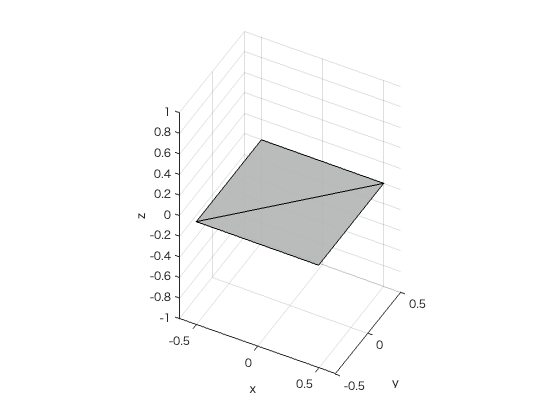

sat.vertices = [0.5 0.5 0
    -0.5 0.5 0
    -0.5 -0.5 0
    0.5 -0.5 0];
sat.faces = [1 2 3
    3 4 1];
[sat.area, sat.pos] = calcAreaObj(sat);
sat.normal = calcNormalObj(sat);
nFacet = size(sat.normal,1); % the number of facet

sat.Cd = [0.5; 0.5];
sat.Cs = [0.5; 0.5];
sat.Ca = 1 - sat.Cd - sat.Cs;
sat.kappa = [0; 0];
sat.F0 = 0.5 .* ones(nFacet, 1);
sat.rho = 0.5;

% check satellite shape
showSC(sat)

## set illumination condition

dAU = 1; % AU
d = au2km(dAU, const) * 10^3; % m
S0 = const.S0; % Solar constant, W/m^2
c = const.c; % light speed, m/s
coeff = -S0 / c / dAU^2;

phiI = deg2rad(60);
thetaI = deg2rad(50);
sunB = [sin(thetaI)*cos(phiI), sin(thetaI)*sin(phiI), cos(thetaI)];
sunB = sunB ./ norm(sunB);

NS = sat.normal * sunB';

% perfect speular direction
pSpecular = 2 * (sat.normal(1,:) * sunB') * sat.normal(1,:) - sunB;

## Lambertian and Perfect Specular Reflection

[sat, cdP, csP] = srpLps(sat, sunB, d, const);

% sat.force; % srp at each facet, N, nx3 matrix
% sat.torque; % srp torques at each facet, Nm, nx3 matrix

srpF = sum(sat.force, 1) % 1x3

srpF = 1.0e-05 *

  -0.055721220013045  -0.096511984122318  -0.377519113337521


srpCd = sum(cdP, 1)

srpCd = 1.0e-06 *

                   0                   0  -0.969851823673556


srpCs = sum(csP, 1)

srpCs = 1.0e-06 *

   0.557212200130451   0.965119841223179  -0.935113103233884


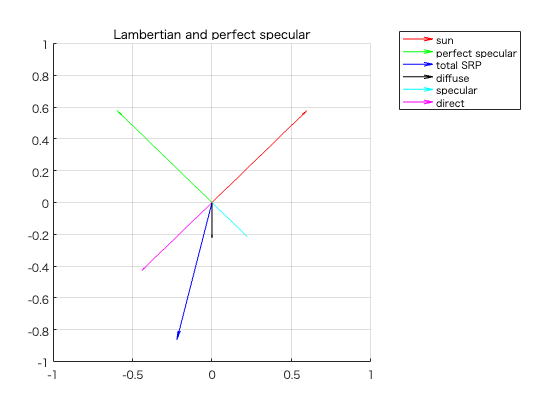

srpDir = sum(coeff .* sat.area .* NS .* sunB, 1);

fNorm = norm(srpF);
srpF = srpF ./ fNorm; % for visualization

figure
quiver3(0,0,0, sunB(1),sunB(2), sunB(3),'r')
hold on
quiver3(0,0,0, pSpecular(1), pSpecular(2), pSpecular(3), 'g')
quiver3(0,0,0, srpF(1), srpF(2), srpF(3),'b')
quiver3(0,0,0, srpCd(1)/fNorm, srpCd(2)/fNorm, srpCd(3)/fNorm,'k')
quiver3(0,0,0, srpCs(1)/fNorm, srpCs(2)/fNorm, srpCs(3)/fNorm,'c')
quiver3(0,0,0, srpDir(1)/fNorm, srpDir(2)/fNorm, srpDir(3)/fNorm,'m')
view([90, 0])
axis equal
xlim([-1 1]), ylim([-1 1]), zlim([-1 1])
legend('sun', 'perfect specular','total SRP', 'diffuse','specular','direct')
title('Lambertian and perfect specular')

## Cook–Torrance model

sat.mCT = 0.12;
[sat, cdCT, csCT] = srpCT(sat, sunB, d, const);

% sat.force; % srp at each facet, N, nx3 matrix
% sat.torque; % srp torques at each facet, Nm, nx3 matrix

srpF = sum(sat.force, 1) % 1x3

srpF = 1.0e-05 *

  -0.058729888050630  -0.101737084378151  -0.374630194914579


srpCd = cdCT

srpCd = 1.0e-06 *

                   0                   0  -0.969851823673556


srpCs = csCT

srpCs = 1.0e-06 *

   0.527125519754601   0.912868838664842  -0.906223919004467


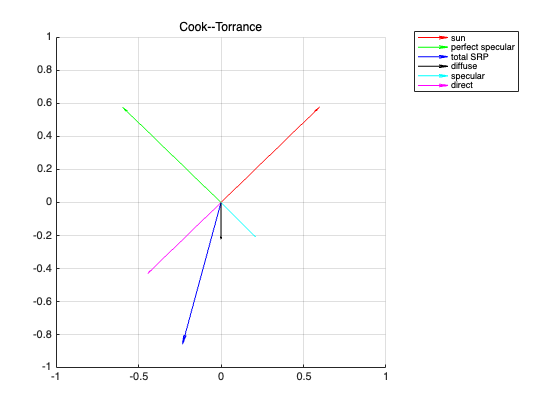

srpDir = sum(coeff .* sat.area .* NS .* sunB, 1);

fNorm = norm(srpF);
srpF = srpF ./ norm(srpF); % for visualization

figure
quiver3(0,0,0, sunB(1),sunB(2), sunB(3),'r')
hold on
quiver3(0,0,0, pSpecular(1), pSpecular(2), pSpecular(3), 'g')
quiver3(0,0,0, srpF(1), srpF(2), srpF(3),'b')
quiver3(0,0,0, srpCd(1)/fNorm, srpCd(2)/fNorm, srpCd(3)/fNorm,'k')
quiver3(0,0,0, srpCs(1)/fNorm, srpCs(2)/fNorm, srpCs(3)/fNorm,'c')
quiver3(0,0,0, srpDir(1)/fNorm, srpDir(2)/fNorm, srpDir(3)/fNorm,'m')
title('Cook--Torrance')
legend('sun', 'perfect specular','total SRP', 'diffuse','specular','direct')
axis equal
xlim([-1 1]), ylim([-1 1]), zlim([-1 1])
view([90, 0])

## Ashikhmin–Shirley model

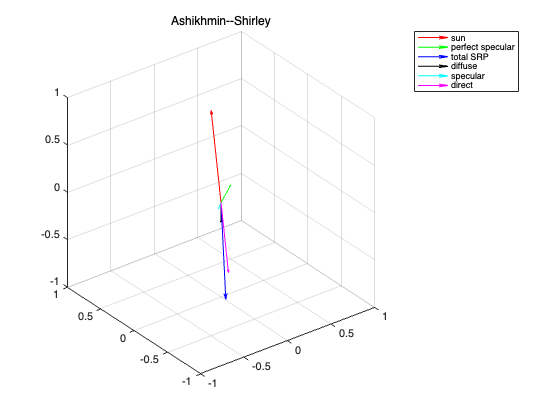

sat.nu = 100 .* ones(nFacet, 1);
sat.nv = 50 .* ones(nFacet, 1);

[sat, cdAS, csAS] = srpAS(sat, sunB, d, const, 10^5);
srpF = sum(sat.force, 1); % 1x3

srpCd = sum(cdAS, 1);
srpCs = sum(csAS, 1);
srpDir = sum(coeff .* sat.area .* NS .* sunB, 1);

% % srpCd + srpCs + srpDir
% % srpF

fNorm = norm(srpF);
srpF = srpF ./ norm(srpF); % for visualization

figure
quiver3(0,0,0, sunB(1),sunB(2), sunB(3),'r')
hold on
quiver3(0,0,0, pSpecular(1), pSpecular(2), pSpecular(3), 'g')
quiver3(0,0,0, srpF(1), srpF(2), srpF(3),'b')
quiver3(0,0,0, srpCd(1)/fNorm, srpCd(2)/fNorm, srpCd(3)/fNorm,'k')
quiver3(0,0,0, srpCs(1)/fNorm, srpCs(2)/fNorm, srpCs(3)/fNorm,'c')
quiver3(0,0,0, srpDir(1)/fNorm, srpDir(2)/fNorm, srpDir(3)/fNorm,'m')
title('Ashikhmin--Shirley')
legend('sun', 'perfect specular','total SRP', 'diffuse','specular','direct')
axis equal
xlim([-1 1]), ylim([-1 1]), zlim([-1 1])